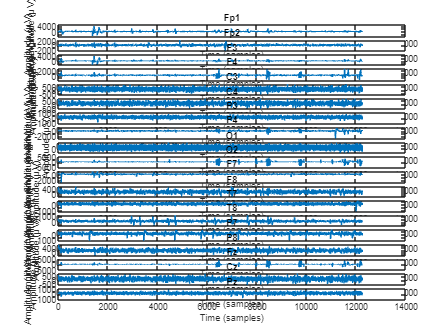

% 

% Load the EEG data and channel labels
load('v1p.mat'); 
channel_labels = {'Fp1', 'Fp2', 'F3', 'F4', 'C3', 'C4', 'P3', 'P4', 'O1', 'O2', ...
                  'F7', 'F8', 'T7', 'T8', 'P7', 'P8', 'Fz', 'Cz', 'Pz'};
              
% Sampling frequency
fs = 128;

% EEG signals for all 19 channels
figure;
tiledlayout(5,20, 'Padding', 'loose', 'TileSpacing', 'loose');

for ch = 1:19
    subplot(19, 1, ch);
    plot(v1p(:, ch));
    title(channel_labels{ch});
    xlabel('Time (samples)');
    ylabel('Amplitude (µV)');
end

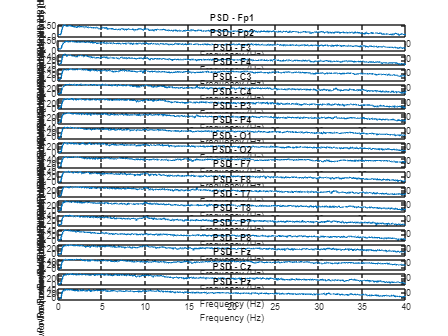


% preprocessing - Bandpass filter (0.5 Hz to 40 Hz)
% filter design
low_cutoff = 0.5;
high_cutoff = 40;
[b, a] = butter(4, [low_cutoff, high_cutoff] / (fs / 2), 'bandpass');

% apply filter to each channel
filtered_eeg = filtfilt(b, a, v1p);

% Power Spectral Density (PSD), using pwelch
% frequency bands
delta_band = [1 4];
theta_band = [4 8];
alpha_band = [8 13];
beta_band = [13 30];

% calculate and visualize the PSD for each channel
figure;
tiledlayout(5,4, 'Padding', 'loose', 'TileSpacing', 'loose');

for ch = 1:19
    [pxx, f] = pwelch(filtered_eeg(:, ch), [], [], [], fs);  % PSD using Welch's method
    
    subplot(19, 1, ch);
    plot(f, 10*log10(pxx));
    xlim([0 40]);
    title(['PSD - ' channel_labels{ch}]);
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
end


% Feature Extraction - Average Power in Frequency Bands
delta_power = zeros(1, 19);
theta_power = zeros(1, 19);
alpha_power = zeros(1, 19);
beta_power = zeros(1, 19);

for ch = 1:19
    [pxx, f] = pwelch(filtered_eeg(:, ch), [], [], [], fs);
    
    % average power in each frequency band
    delta_power(ch) = bandpower(pxx, f, delta_band, 'psd');
    theta_power(ch) = bandpower(pxx, f, theta_band, 'psd');
    alpha_power(ch) = bandpower(pxx, f, alpha_band, 'psd');
    beta_power(ch) = bandpower(pxx, f, beta_band, 'psd');
end

% power in each band for all channels
disp('Delta Power:');

Delta Power:


disp(delta_power);

   1.0e+05 *

    0.7575    0.3668    0.4597    0.2099    0.0729    0.0828    0.0670    0.1988    0.0407    1.0488    0.0978    0.0482    0.0313    0.1304    0.1129    0.0383    0.7670    0.0822    0.0608



disp('Theta Power:');

Theta Power:


disp(theta_power);

   1.0e+04 *

    1.4468    1.3191    0.7642    0.8692    0.6846    0.7863    0.4877    0.7997    0.2787    5.1596    0.4177    0.2626    0.1544    0.4802    0.1938    0.2361    3.1952    0.8383    0.4729



disp('Alpha Power:');

Alpha Power:


disp(alpha_power);

   1.0e+04 *

    0.5405    0.8853    0.3911    0.4800    0.3429    0.5012    0.3579    0.4906    0.1808    2.0391    0.2517    0.1630    0.1229    0.3201    0.1024    0.2072    1.2189    0.4590    0.3591



disp('Beta Power:');

Beta Power:


disp(beta_power);

   1.0e+04 *

    0.3423    1.0661    0.2746    0.8027    0.1514    0.1515    0.1867    0.3327    0.1486    5.8777    0.1340    0.0991    0.0899    0.1121    0.0882    0.1551    3.5558    0.1539    0.1613

